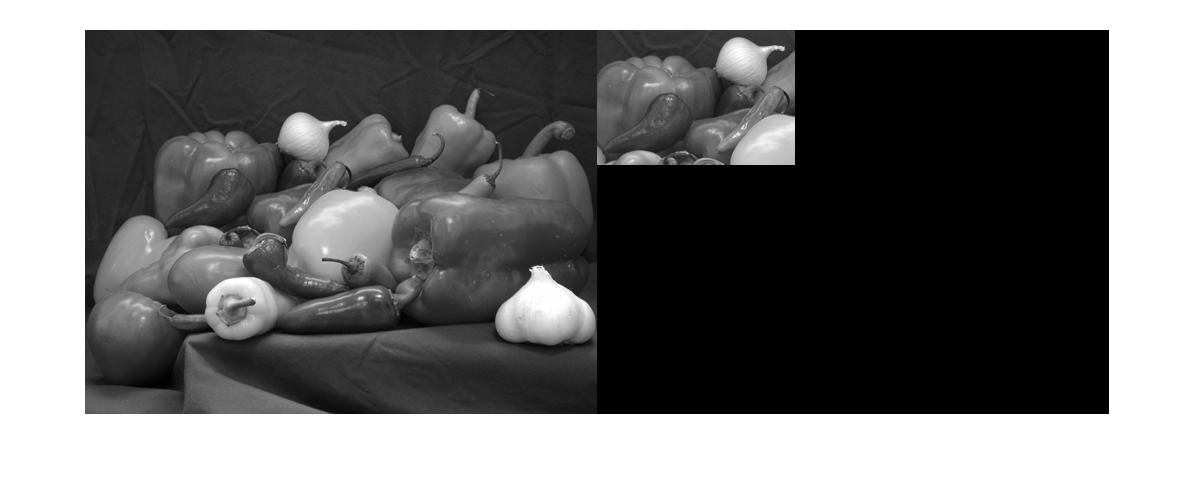

onion = rgb2gray(imread('onion.png'));
peppers = rgb2gray(imread('peppers.png'));
imshowpair(peppers,onion,'montage');

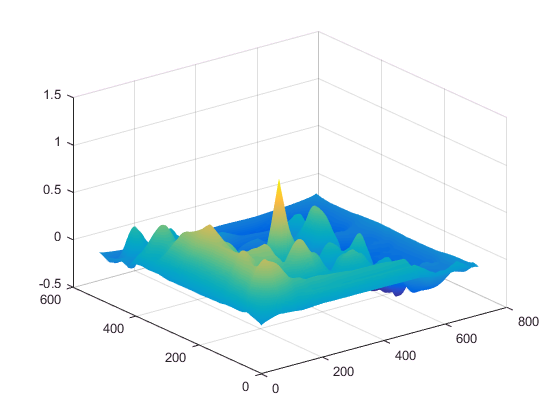


% normalized cross-correlation
c=normxcorr2(onion,peppers);
figure, surf(c), shading flat

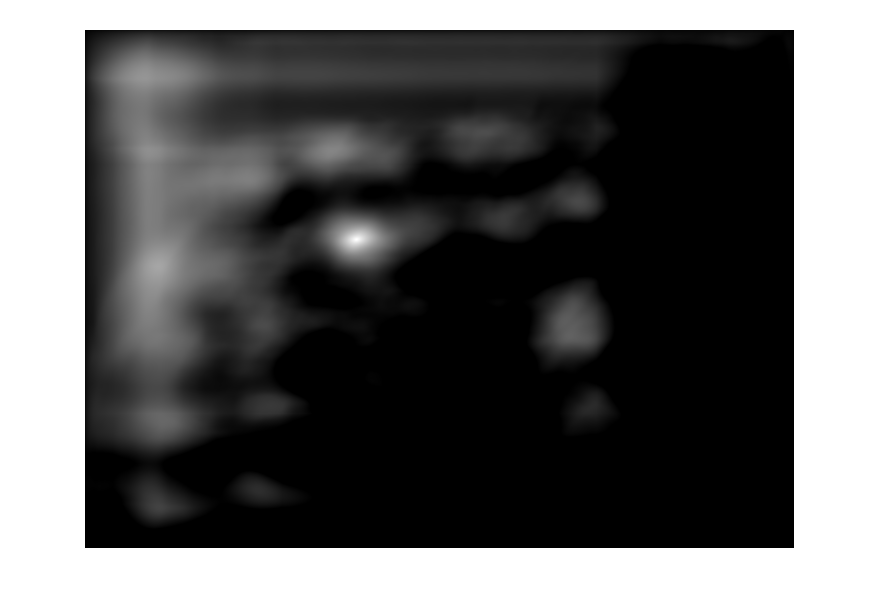

% there will be a spike when filter lands on the image it was taken from

% you will see a bright spot where given template perfectly matched
imshow(c);

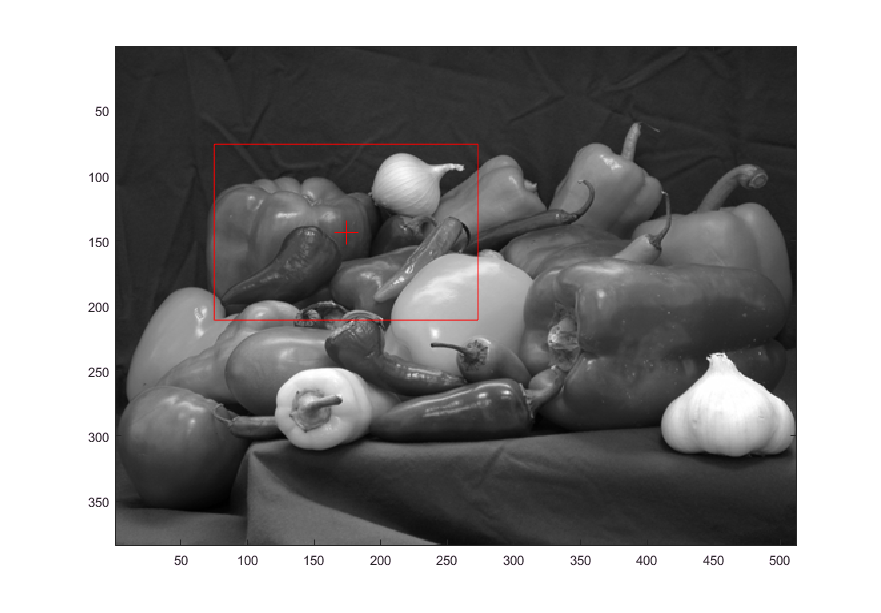

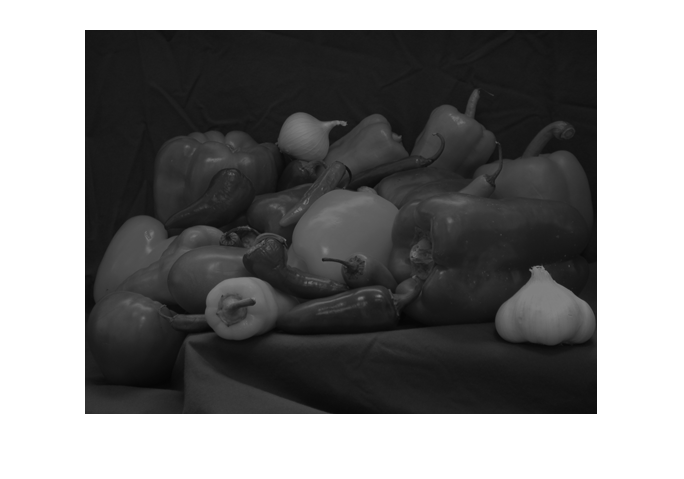

%something = peppers(300:350,150:250);
% max(c) would compute column-wise maximum. use c(:) to flatten it
[yRaw xRaw]=find(c==max(c(:)));

% top left index of the column
y=yRaw-size(onion,1)+1;
x=xRaw-size(onion,2)+1;
% plot on the image to show where we found the template
xLength = size(onion,2);
yLength = size(onion,1);
imagesc(peppers);
hold on;
plot(x+xLength/2,y+yLength/2,'r+','markersize',16);
rectangle('Position',[x,y,xLength,yLength],'EdgeColor','r');
hold off;

Find template 1D

s=[-1 0 0 1 1 1 0 -1 -1 0 1 0 0 -1];
t=[1 1 0];

% find where template t occurs in a signal s
disp('Signal:'), disp([1:size(s,2);s]);

Signal:
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
    -1     0     0     1     1     1     0    -1    -1     0     1     0     0    -1



disp('Template:'),disp([1:size(t,2);t]);

Template:
     1     2     3
     1     1     0




% find correlation maximum
c=normxcorr2(t,s);
[maxValue rawIndex] = max(c);
index=rawIndex-size(t,2)+1;
disp('Index:'),disp(index);

Index:
     5



Find template 2D